clc;
clear;
close all;

%% Step 1: Select NIfTI file
[file, path] = uigetfile('*.nii', 'Select CT or MRI NIfTI file');
filename = fullfile(path, file);

%% Step 2: Read NIfTI file
V = niftiread(filename);
info = niftiinfo(filename);

%% Step 3: Display scan information
disp('===== NIfTI File Information =====');

===== NIfTI File Information =====


disp(info);

                 Filename: 'C:\old_D\Roshan\College Work\MRICT\Task1\brain\1BA001\ct.nii'
              Filemoddate: '16-Mar-2026 23:08:19'
                 Filesize: 45993376
                  Version: 'NIfTI1'
              Description: ''
                ImageSize: [231 244 204]
          PixelDimensions: [1 1 1]
                 Datatype: 'single'
             BitsPerPixel: 32
               SpaceUnits: 'Millimeter'
                TimeUnits: 'None'
           AdditiveOffset: 0
    MultiplicativeScaling: 1
               TimeOffset: 0
                SliceCode: 'Unknown'
       FrequencyDimension: 0
           PhaseDimension: 0
         SpatialDimension: 0
    DisplayIntensityRange: [0 0]
            TransformName: 'Qform'
                Transform: [1×1 affine3d]
                  Qfactor: 1
                      raw: [1×1 struct]




%% Step 4: Show size of scan
[m,n,p] = size(V);
fprintf('Scan size: %d x %d x %d\n', m,n,p);

Scan size: 231 x 244 x 204


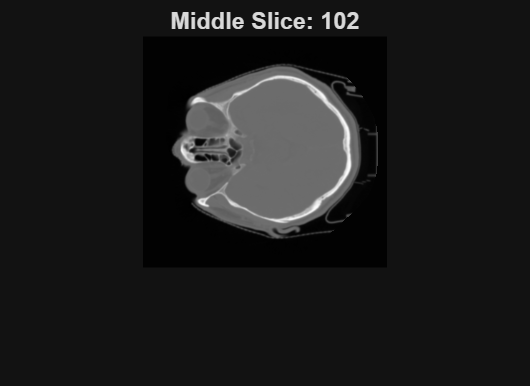


%% Step 5: Display middle slice
figure;
mid_slice = round(p/2);
imshow(V(:,:,mid_slice),[]);
colormap gray
title(['Middle Slice: ', num2str(mid_slice)])

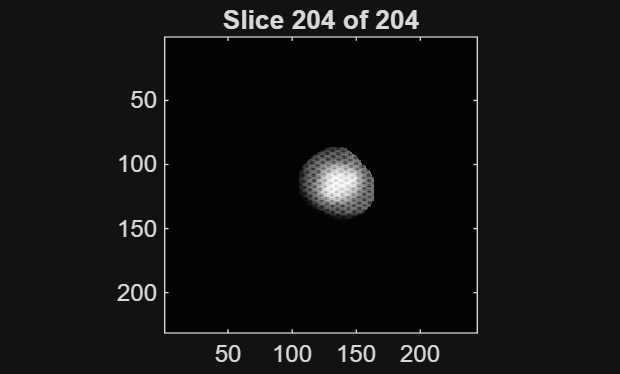


%% Step 6: Scroll through slices automatically
figure;
for i = 1:p
    imagesc(V(:,:,i));
    colormap gray
    axis image
    title(['Slice ', num2str(i), ' of ', num2str(p)]);
    pause(0.05);
end

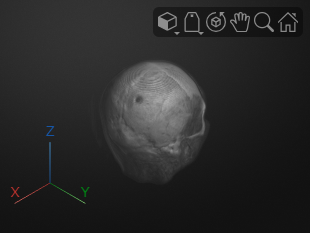

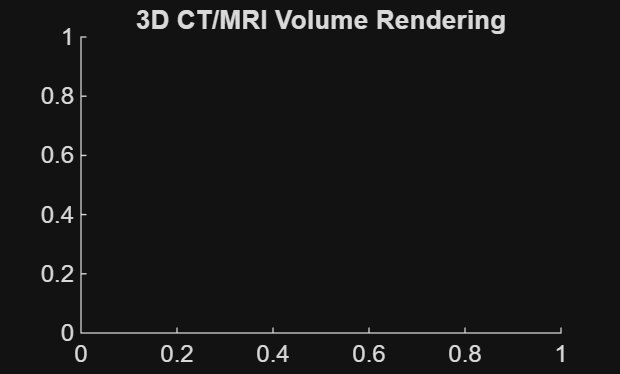


%% Step 7: Interactive slice viewer
figure;
sliceViewer(V);
title('Interactive CT/MRI Slice Viewer');

%% Step 8: 3D Volume Rendering (if supported)
try
    figure;
    volshow(V);
    title('3D CT/MRI Volume Rendering');
catch
    disp('3D volume viewer not supported in this MATLAB version');
end